# **INCLASS Chapter#10 Group#1**

## **10.8.1**

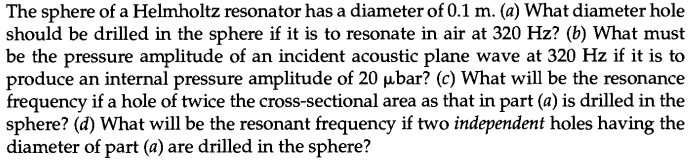

(a) 

c = 343;


f = 320;
omega_0 = 2*pi*f;

D = 0.1;
V = (pi*D^3)/6;
syms d
S = (pi*d^2)/4;

L = 0;
L_prime = L + 2*(0.85*(d/2));

f1 = omega_0 == c*sqrt(S/(L_prime*V));
sol = solve(f1, d);
sol(1);
vpa(sol(1), 2)

$$ans = 0.019$$

(b) 

d = vpa(sol(1), 2);
S = (pi*d^2)/4;
L_prime = L + 2*(0.85*(d/2));
Q = 2*pi*sqrt(V * (L_prime/S)^3);
P_c = 20;
syms P
f2 = P_c/P == Q;
solve(f2, P)

$$ans = 0.33570354647927427374843119190986$$

(c) 

f_r  = (c/(2*pi))*sqrt((2*S)/(V*(L_prime)))

$$f\_r = 452.54833988140564956996759310043$$

(d) 

r_1 = (sqrt(2)/2)*(d);

f_r1 = f * sqrt(2*(d/2)/r_1);
vpa(f_r1, 4)

$$ans = 380.5$$